## **Peak Detection Algorithms**

Peak detection for an ECG signal from the MIT-BIH Arrhythmia Database (mitdb) [1] using different algorithms.

record = 208; % Entre 100 y 234
% Descargar archivo m.mat
mat_url = ['https://archive.physionet.org/atm/mitdb/' num2str(record) '/atr/0/e/export/matlab/' num2str(record) 'm.mat'];
mat_filename = [num2str(record) 'm.mat'];
websave(mat_filename, mat_url);

load (mat_filename);
ecg = val(1, :);

Pan and Tompkins algorithm [2]

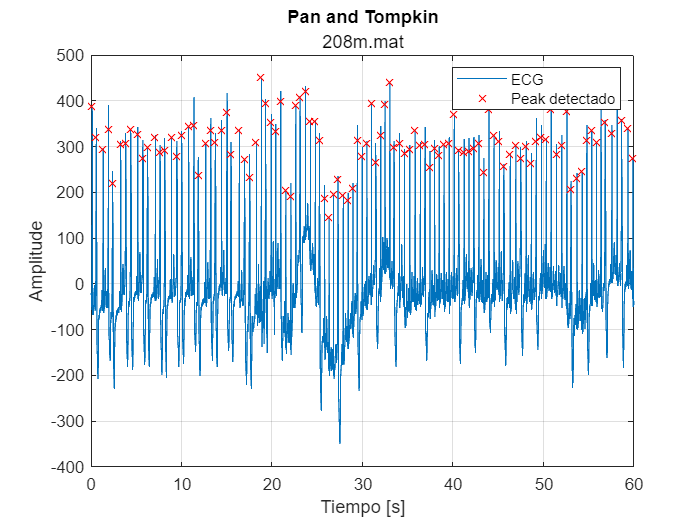

start=1;
l=length(val)-start+1;
fs = 360;
t=(start:start+l-1)/fs; %tiempo en segundos
[qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(ecg,fs,0);

tp = (qrs_i_raw - delay)/(360);

%Se grafica la senal Pan and Tompkin
figure()
plot(t,ecg,tp,ecg(qrs_i_raw),'xr')
legend('ECG','Peak detectado')
ylabel('Amplitude')
xlabel('Tiempo [s]')
xlim ([0 60]) 
title('Pan and Tompkin', mat_filename)
grid on

Peak algorithm [3]

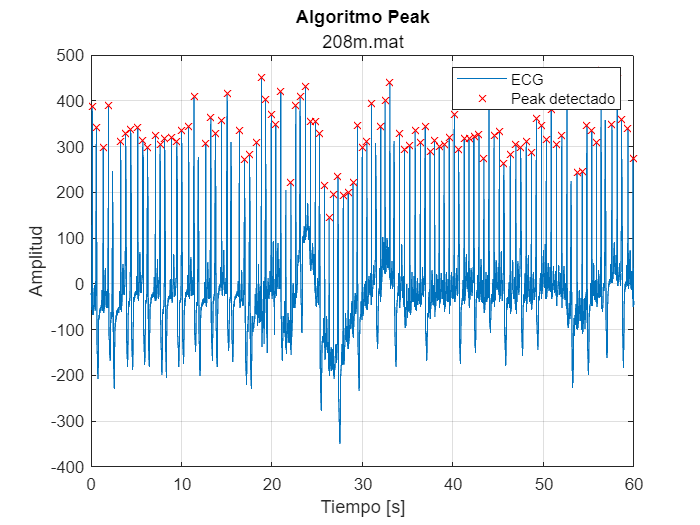

[ma, mi, thres, tp, ip, t2] = peak_detection(ecg, fs);
% Graficar la señal ECG y los picos detectados
figure();
plot(t2, ecg, tp, ecg(ip), 'xr');
legend('ECG', 'Peak detectado');
ylabel('Amplitud');
xlabel('Tiempo [s]');
xlim ([0 60]) 
title('Algoritmo Peak', mat_filename);
grid on;

Peak + Wavelet algorithm

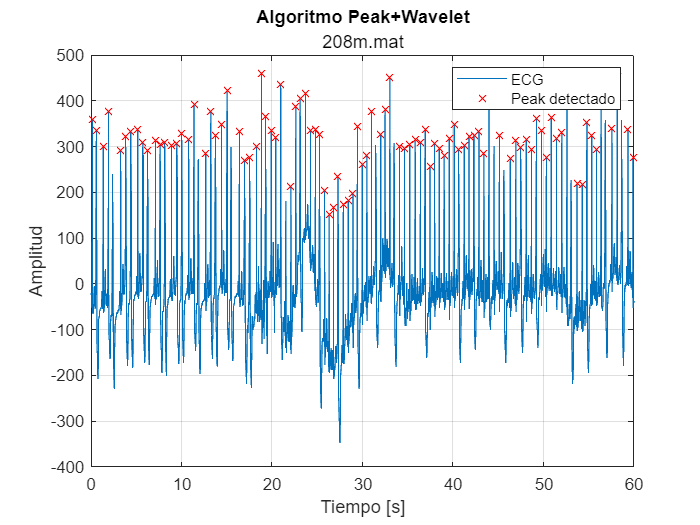

% Descomponer la señal ECG en 8 niveles utilizando el bior6.8 wavelet
[coefficients,levels] = wavedec(ecg,8,'bior6.8');

% Reconstruir la señal ECG a partir de los coeficientes de detalle de los primeros 7 niveles
reconstruccionECG = wrcoef('a',coefficients,levels,'bior6.8',2);

% Detectar los picos R en la señal ECG
[ma3, mi3, thres3, tp3, ip3, t3] = peak_detection(reconstruccionECG, fs);
% Graficar la señal ECG y los picos detectados
figure();
plot(t3, reconstruccionECG, tp3, reconstruccionECG(ip3), 'xr');
legend('ECG', 'Peak detectado');
ylabel('Amplitud');
xlabel('Tiempo [s]');
xlim ([0 60])  
title('Algoritmo Peak+Wavelet', mat_filename);
grid on;

function [ma, mi, thres, tp, ip, t] = peak_detection(ecg, fs)
    start = 1;
    l = length(ecg);

    % ECG sin valor medio
    ecg = ecg(:) - mean(ecg);

    % prepara vectores para optimizar velocidad de ejecución
    thres = zeros(l, 1);
    ma = thres;
    mi = ma;
    index = 1;

    for i = 31:(l - 30)
        % segmento completo
        ma(i) = max(ecg(i - 30:i + 30));

        % segmento central
        mi(i) = max(ecg(i - 10:i + 10));

        if (ma(i) < thres(i - 1))
            % si thres > max, actualiza thresh
            thres(i) = ma(index) - (ma(index) - ma(i)) * ((i - index) / 408);
            if (thres(i) > thres(i - 1))
                % thresh no puede ser mayor al anterior como resultado del
                % calculo
                thres(i) = thres(i - 1);
            end
        else
            % thres se actualiza inmediatamente al valor del max
            thres(i) = ma(i);
            index = i;
        end
    end

    % tiempo en segundos
    t = (start:start + l - 1) / fs ;

    % busca puntos cuando el ECG = thresh
    ip = find(ecg == thres);
    % tiempo de los peaks
    tp = t(ip);
end

[1] Data available in a publicly accessible repository. The data presented in this work are openly available in Physiobank ATM: [https://archive.physionet.org/cgi-bin/atm/ATM](https://archive.physionet.org/cgi-bin/atm/ATM) (accessed on 1 July 2023).

[2] PAN.J, TOMPKINS. W.J,"A Real-Time QRS Detection Algorithm" IEEE TRANSACTIONS ON BIOMEDICAL ENGINEERING, VOL. BME-32, NO. 3, MARCH 1985.

[3] Pino E, Ohno-Machado L, Wiechmann E, Curtis D. "Real-time ECG algorithms for ambulatory patient monitoring". AMIA Annu Symp Proc. 2005;2005:604-8. PMID: 16779111; PMCID: PMC1560458.